# Homework 5

## T13.3a

clear
mooreslaw

t = T(:,1);
N = T(:,2);
y = log10(N);
plot(t, y, 'ro')
title('Data Points')

y_hat = @(theta, x) theta(1) + theta(2) * (x - 1970);
theta0 = [0 1];
[theta, resnorm, ~, exitflag, output] = lsqcurvefit(y_hat, theta0, t, y)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


theta =     3.1256    0.1540


resnorm = 0.5361

exitflag = 1

output = struct with fields:
    firstorderopt: 1.2600e-08
       iterations: 1
        funcCount: 6
     cgiterations: 0
        algorithm: 'trust-region-reflective'
         stepsize: 3.2381
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 1.260008e-08,↵is less than options.OptimalityTolerance = 1.000000e-06.'


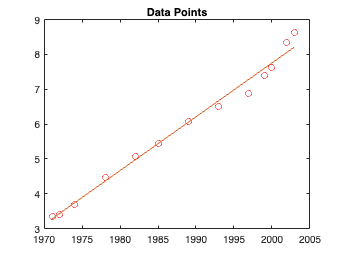


hold on
plot(t, y_hat(theta, t))


RMS = sqrt(1/length(N) * resnorm)

RMS = 0.2031

## T13.3b

y_2015 = y_hat(theta, 2015)

y_2015 = 10.0564


error = ((10^y_2015 - 4e9) / 4e9) * 100

error = 184.6759

y_2013 = y_hat(theta, 2013)

y_2013 = 9.7484


projection = 10^y_2015 / 10^y_2013

projection = 2.0325

The projection corresponds with Moore's law

## A8.3

## A8.6